# Why does it shake? Rotating Unbalance Activity

**MECC 2026 · Special Session · Hands-on activity · Teams of 2–3 · 15 minutes**

Turbines, fans and motors vibrate when their mass sits off the axis of rotation. In 15 minutes you will predict, see and explain it on a real rig.

**The plan:**  **Read**  →  **Characterize the system** (free response)  →  **Predict**  →  **Observe four disk setups**  →  **Explain & discuss**

**How to use this Live Script:** run one section at a time (click inside a section, then **Run Section**, or Ctrl+Enter / Cmd+Enter). Lines ending in **EDIT** are the values your team enters.

## 1  Read: on the bench

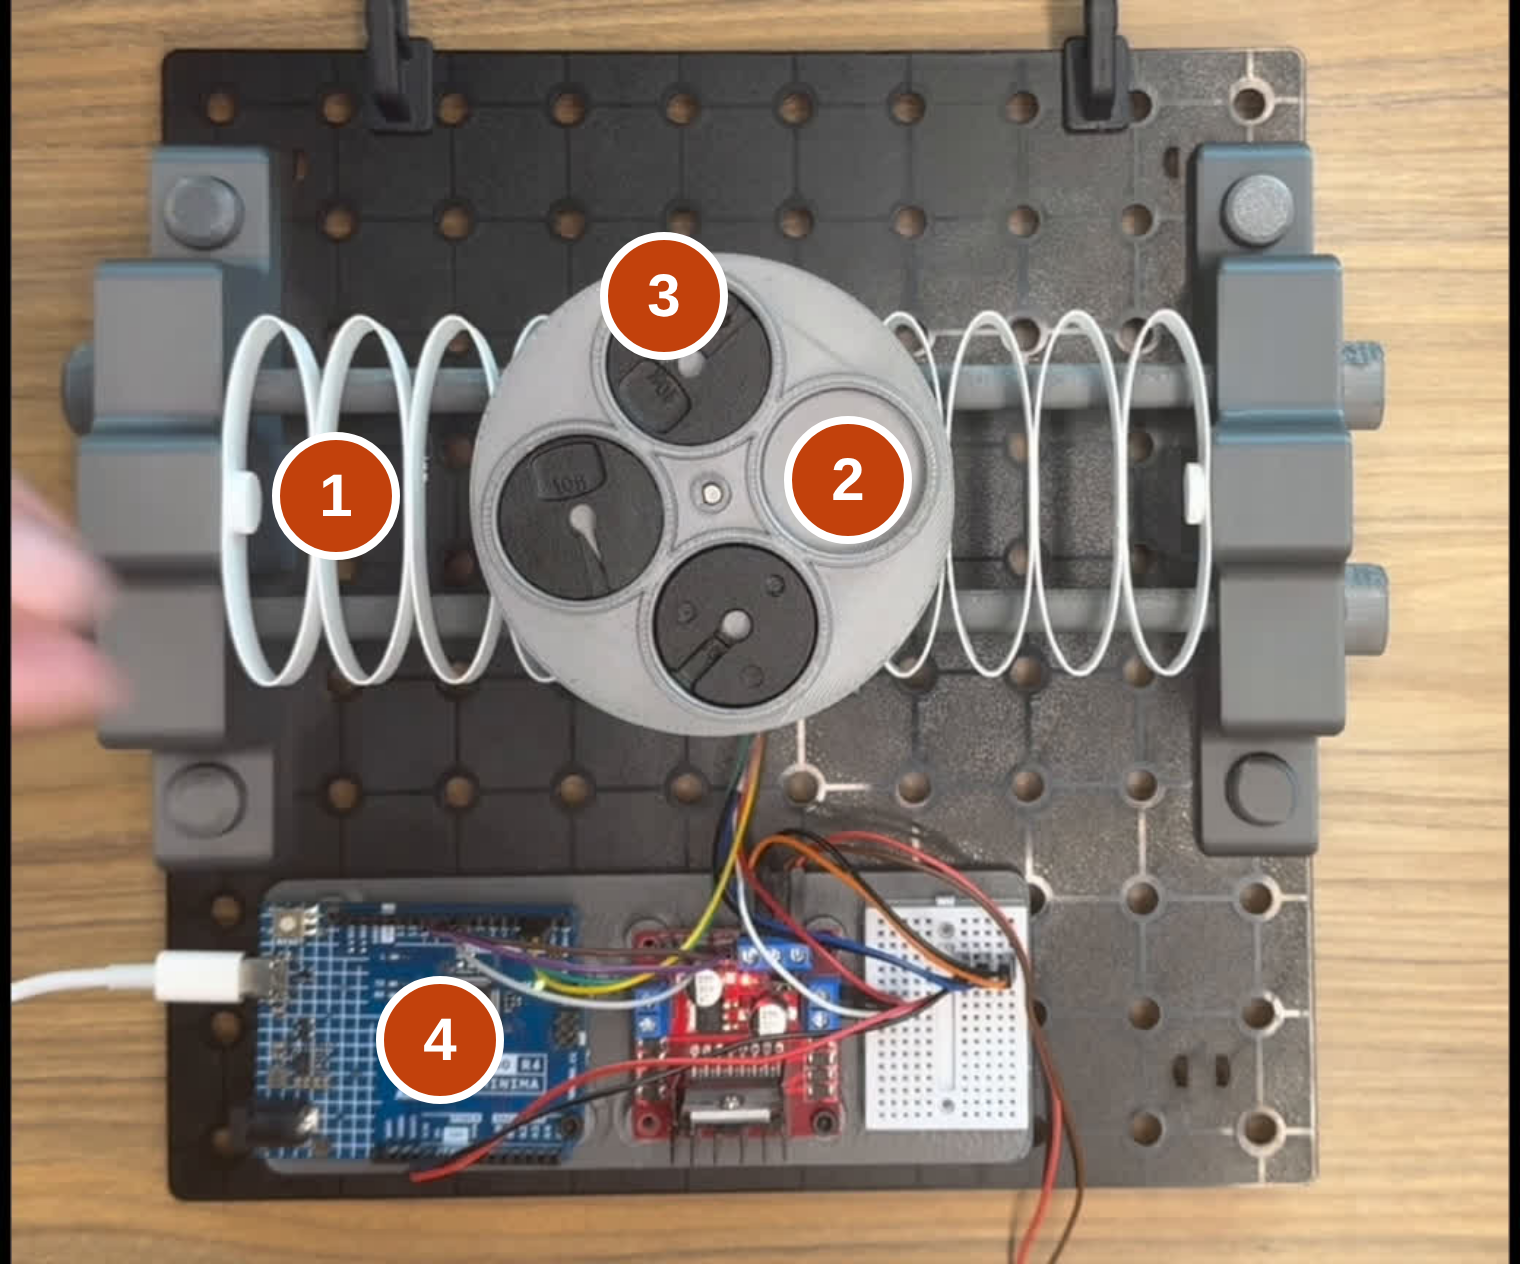

**1 Cart + springs** on two guide rods: the vibrating system (mass *m*, stiffness *k*).

**2 Spinning disk** with four pockets, driven by a motor under the cart.

**3 Snap-in holders** with slotted weights: the unbalanced mass $m_0$ at radius *e*.

**4 Arduino UNO R4 + motor driver** set the disk speed $\omega$.

**Safety:** keep fingers clear of the spinning disk. Stop the motor before you swap holders.

**By the end you can:**  (1) explain why an off-center mass makes a force that grows with speed;  (2) predict whether a mass arrangement is balanced or unbalanced;  (3) name the parameters that set how much the cart vibrates.

## The key idea

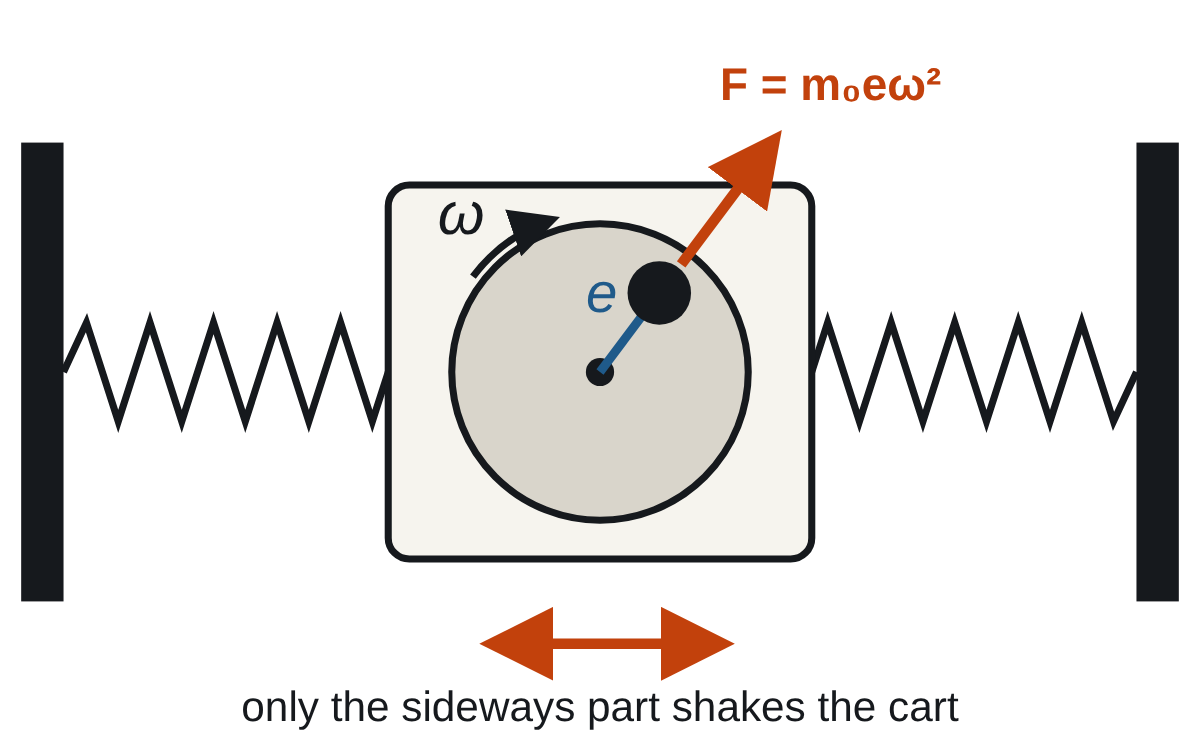

**Equation of motion:**


$$m\ddot{x} +c\dot{x} +kx=m_0 e\,\omega^2 \sin \omega t$$


**Steady-state amplitude:**


$$X=\frac{m_0 e}{m}\cdot \frac{r^2 }{\sqrt{(1-r^2 )^2 +(2\zeta r)^2 }}$$


with $r=\omega /\omega_n$ and $\omega_n =\sqrt{k/m}$.

**Unbalance adds like arrows.** Each holder is an arrow from the shaft; only the net arrow shakes the cart.

**Speed counts twice.** Force grows with $\omega^2$, and the response peaks near $r\approx 1$.

## Setup: connect to the Arduino

Plug in the Arduino and run this section once. It finds the Arduino on any USB port by itself. If it can't, it prints the ports it sees; copy the right one into **PORT**. The **ADXL335 accelerometer** on the slider is read on pin **A2**; every run records the cart's acceleration. Set **useHardware = false** to try the script without the rig (simulated data).

clear; close all;

% Add the helpers folder (next to this Live Script) to the MATLAB path
here = fileparts(matlab.desktop.editor.getActiveFilename);
if isempty(here) || ~isfolder(fullfile(here, "helpers")), here = pwd; end
addpath(fullfile(here, "helpers"));

useHardware = true;                 % false = demo mode (no Arduino, motor commands are only printed)

PORT  = "";     % leave empty to find the Arduino automatically (any USB port, Mac or Windows)
% PORT = "/dev/tty.usbmodem101";   % or set it by hand (Mac). Windows example: "COM3"
BOARD = "UnoR4Minima";

speed   = 0.8;    % motor PWM duty cycle (0 to 1). Keep the SAME for setups A-D
runTime = 10;     % seconds the disk spins in each setup

loadMass_g   = 10;   % mass of one slotted load (g)
holderMass_g = 0;    % mass of an empty holder (g), if you want to include it   <-- EDIT
cfg = struct();      % stores how each setup was loaded and its acceleration data

% Moving mass of the cart (measured)
motorHousing_g = 114;   % motor + housing (g)        <-- EDIT
disk_g         = 22;    % empty disk (g)             <-- EDIT
spring_g       = 11;    % one spring (g)             <-- EDIT
nSprings       = 2;     % one spring on each side
m_g  = motorHousing_g + disk_g + nSprings*spring_g/3;   % a spring moves with about 1/3 of its mass
m_kg = m_g/1000;

% ADXL335 accelerometer on the slider (one axis, along the slider)
accel.pin          = "A2";    % analog pin                                      <-- EDIT if needed
accel.sens         = 0.330;   % sensitivity (V per g); 0.330 at 3.3 V supply     <-- EDIT
accel.baselineTime = 1;       % s of motor-off data before each run (sets zero)
accel.coastTime    = 1;       % s of data after the motor stops
accel.zeroV        = 1.65;    % nominal 0 g voltage (only used in demo mode)

if useHardware
    if strlength(PORT) == 0
        PORT = findArduinoPort();
    end
    fprintf("Using serial port %s. Connecting (this can take up to a minute)...\n", PORT);
    a = arduino(PORT, BOARD);
    disp("Arduino connected.")
else
    a = [];
end

Serial ports seen: /dev/cu.wlan-debug, /dev/tty.wlan-debug, /dev/cu.debug-console, /dev/tty.debug-console, /dev/cu.JabraEvolve65, /dev/tty.JabraEvolve65, /dev/cu.Bluetooth-Incoming-Port, /dev/tty.Bluetooth-Incoming-Port, /dev/cu.usbmodem2101, /dev/tty.usbmodem2101


Using serial port /dev/tty.usbmodem2101. Connecting (this can take up to a minute)...


Arduino connected.


pins = motorSetup(a);     % L298N driver: IN1 = D8, IN2 = D7, ENA = D9 (PWM)

Motor stopped
Arduino connected and motor pins configured.


if useHardware
    configurePin(a, accel.pin, 'AnalogInput');
    fprintf("ADXL335 on %s reads %.3f V at rest.\n", accel.pin, readVoltage(a, accel.pin));
end

ADXL335 on A2 reads 1.660 V at rest.


fprintf("Moving mass m = %.1f g (motor + housing + disk + 1/3 of the springs)\n", m_g);

Moving mass m = 143.3 g (motor + housing + disk + 1/3 of the springs)


## 2  Characterize the system (free response)

Before adding any mass, find the cart's **natural frequency, damping and spring stiffness**. With the motor off and no holders on the disk, the cart is a simple mass–spring–damper:


$$m\ddot{x} +c\dot{x} +kx=0$$


**How to run the test:** one teammate pulls the cart about **3 cm** to the right or left and **holds it still**. The other runs this section and clicks **Start recording** in the window. After a beep and **RELEASE NOW**, let go of the cart (don't push it). The script records 8 s of acceleration.

In free vibration the acceleration decays exactly like the displacement, so its peaks give the same logarithmic decrement and damped period.

free = recordFreeResponse(a, accel, 8);

Hold the cart still...
>>> RELEASE NOW <<<
Recorded 425 samples at about 47 samples/s.


free = findFreePeaks(free);

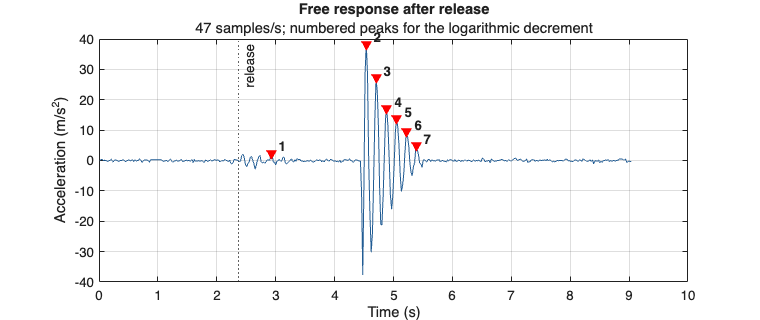

plotFreeResponse(free);

saveAccel(free);

Saved /Users/atekes/Desktop/MECC Educational Session/Rotating Unbalance/version 4/Setup_Free_accel.csv


Pick two peaks **n cycles apart, early in the decay**, and enter them below. Skip the very first peak at the moment of release. The table lists every detected peak.

disp(free.peaks)

    Peak    Time_s    Accel_m_s2
    ____    ______    __________

     1      2.9248      2.4476  
     2       4.538      38.301  
     3      4.7093      27.262  
     4      4.8819      17.061  
     5      5.0542      13.779  
     6      5.2238      9.4301  
     7       5.388      4.8526  




firstPeak = 2;    % number of the first peak you picked       <-- EDIT
n         = 3;    % how many cycles later the second peak is  <-- EDIT

if firstPeak + n > height(free.peaks)
    error('Only %d peaks detected: choose a smaller n or an earlier firstPeak.', height(free.peaks));
end
a1  = free.peaks.Accel_m_s2(firstPeak);     t1  = free.peaks.Time_s(firstPeak);
aN1 = free.peaks.Accel_m_s2(firstPeak+n);   tN1 = free.peaks.Time_s(firstPeak+n);
fprintf('a_1   = %6.3f m/s^2   at t_1   = %.3f s\n', a1,  t1);

a_1   = 38.301 m/s^2   at t_1   = 4.538 s


fprintf('a_n+1 = %6.3f m/s^2   at t_n+1 = %.3f s   (n = %d cycles)\n', aN1, tN1, n);

a_n+1 = 13.779 m/s^2   at t_n+1 = 5.054 s   (n = 3 cycles)


Find the system parameters:


$$\delta =\frac{1}{n}\ln \frac{a_1 }{a_{n+1} },~~\zeta =\frac{\delta }{\sqrt{4\pi^2 +\delta^2 }},~~T_d =\frac{t_{n+1} -t_1 }{n},~~\omega_d =\frac{2\pi }{T_d },~~\omega_n =\frac{\omega_d }{\sqrt{1-\zeta^2 }}$$



$$k_{eq} =m\,\omega_n^2 ,~~~~c=2\zeta m\,\omega_n$$


delta  = (1/n)*log(a1/aN1);            % logarithmic decrement
zeta   = delta/sqrt(4*pi^2 + delta^2); % damping ratio
Td     = (tN1 - t1)/n;                 % damped period (s)
wd     = 2*pi/Td;                      % damped natural frequency (rad/s)
wn     = wd/sqrt(1 - zeta^2);          % natural frequency (rad/s)
fn     = wn/(2*pi);                    % natural frequency (Hz)
k_eq   = m_kg*wn^2;                    % equivalent stiffness of both springs (N/m)
k_each = k_eq/nSprings;                % each spring (they act in parallel on the cart)
c      = 2*zeta*m_kg*wn;               % damping constant (N*s/m)

Parameter = ["m"; "delta"; "zeta"; "T_d"; "omega_d"; "omega_n"; "f_n"; "k_eq"; "k (each spring)"; "c"];
Value     = [m_kg; delta; zeta; Td; wd; wn; fn; k_eq; k_each; c];
Units     = ["kg"; "-"; "-"; "s"; "rad/s"; "rad/s"; "Hz"; "N/m"; "N/m"; "N*s/m"];
sysParams = table(Parameter, Value, Units)

sysParams = 10×3 table
        Parameter         Value       Units 
    _________________    ________    _______

    "m"                   0.14333    "kg"   
    "delta"               0.34079    "-"    
    "zeta"               0.054159    "-"    
    "T_d"                 0.17208    "s"    
    "omega_d"              36.512    "rad/s"
    "omega_n"              36.566    "rad/s"
    "f_n"                  5.8196    "Hz"   
    "k_eq"                 191.65    "N/m"  
    "k (each spring)"      95.823    "N/m"  
    "c"                    0.5677    "N*s/m"


**Check:** the dashed line rebuilds the free response from your $\zeta$ and $\omega_n$. Does it sit on the data?

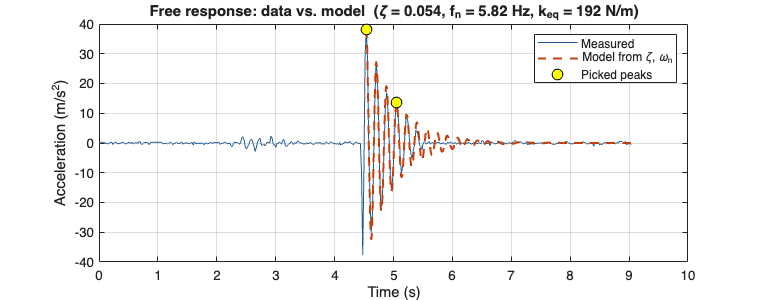

tm = linspace(t1, free.t(end), 800);
aModel = a1*exp(-zeta*wn*(tm - t1)).*cos(wd*(tm - t1));
figure('Position', [100 100 760 300]);
plot(free.t, free.acc, 'Color', [0.13 0.36 0.58]); hold on;
plot(tm, aModel, '--', 'Color', [0.76 0.25 0.05], 'LineWidth', 1.5);
plot([t1 tN1], [a1 aN1], 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)'); grid on;
title(sprintf('Free response: data vs. model  (\\zeta = %.3f, f_n = %.2f Hz, k_{eq} = %.0f N/m)', zeta, fn, k_eq));
legend('Measured', 'Model from \zeta, \omega_n', 'Picked peaks');

Your cart is now characterized. The forced runs below use $\omega_n$ to find the frequency ratio $r=\omega /\omega_n$.

## 3  Predict

Before you spin anything: for **all four setups**, predict how much the cart will shake and draw the **net unbalance arrow** on your worksheet. In the suggested setups each holder carries one load; your team can change the loads in each holder in the setup window.

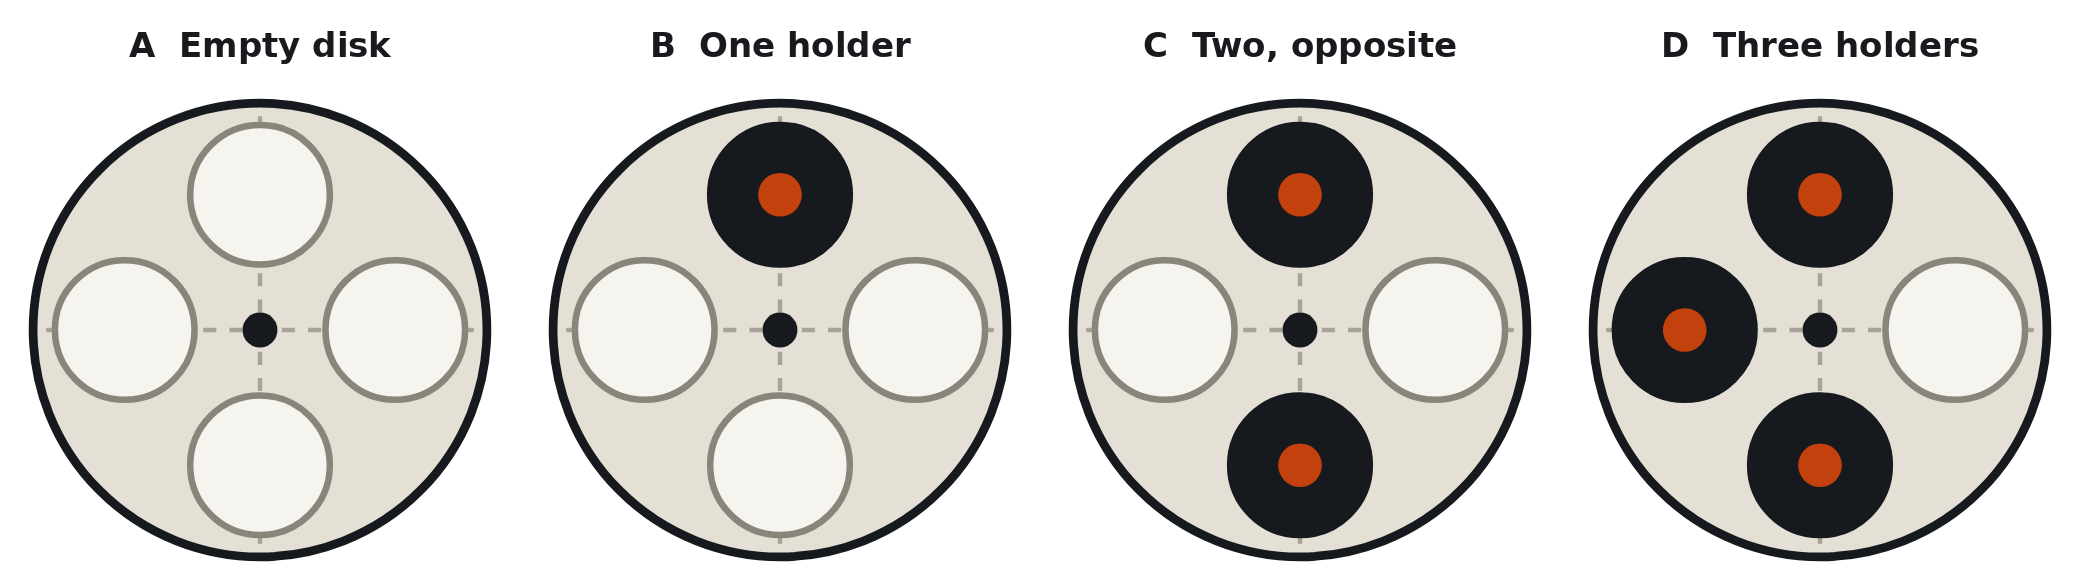

Setup      = ["A: no load"; "B: one holder"; "C: two, opposite"; "D: three holders"];
Prediction = ["?"; "?"; "?"; "?"];     % type "none", "small" or "large" for each   <-- EDIT
table(Setup, Prediction)

ans = 4×2 table
          Setup           Prediction
    __________________    __________

    "A: no load"             "?"    
    "B: one holder"          "?"    
    "C: two, opposite"       "?"    
    "D: three holders"       "?"    


## 4  Observe: Setup A (no load)

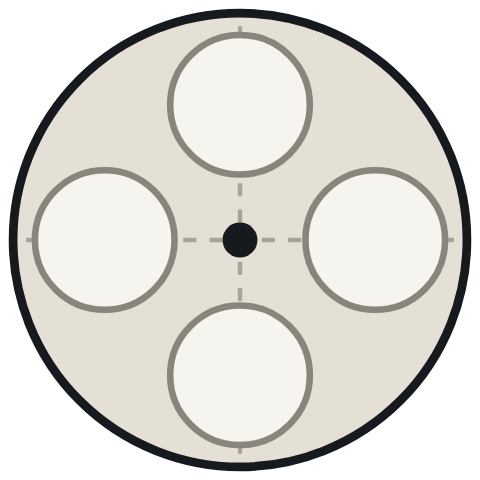

First run the system **with no load**. Remove **all holders** from the disk, then run this section. A window shows the empty disk and waits until you click **Start motor**. The script records 1 s at rest, spins the disk for 10 s, and keeps recording 1 s as it stops. Watch the cart.

Setup A: set up the disk in the pop-up window...
Setup A: empty disk.


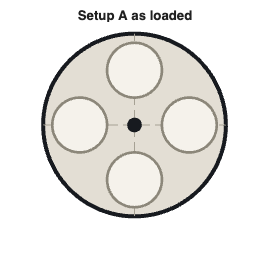

Starting in 3...
Starting in 2...
Starting in 1...


cfg.A = setupDisk("A", [], 0, loadMass_g, holderMass_g);

Recording 1 s at rest...
Motor ON: 80% PWM for 10 s, recording acceleration...
Done: 561 samples at about 46 samples/s. RMS acceleration while spinning: 1.684 m/s^2
Motor stopped


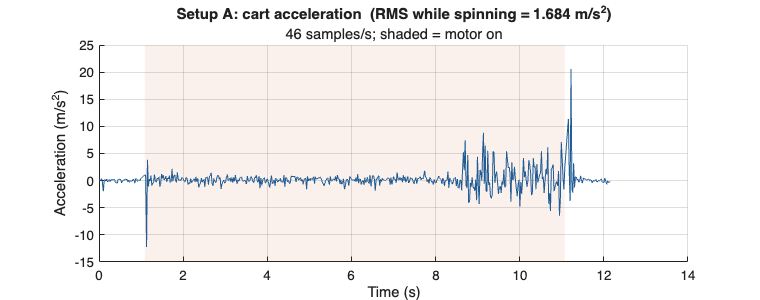

Saved /Users/atekes/Desktop/MECC Educational Session/Rotating Unbalance/version 4/Setup_A_accel.csv


if cfg.A.ready
    cfg.A.data = runMotor(a, pins, speed, runTime, accel, cfg.A);
    plotAccel(cfg.A.data);
    saveAccel(cfg.A.data);
end

## Setup B (one holder)

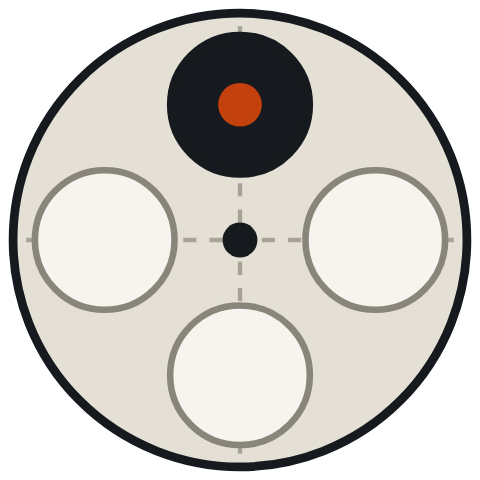

Run this section. A window opens: tick **which pockets** get a holder and set **how many 10 g loads** go in each one. Holders can carry different numbers of loads. The picture in the window shows where to put them. Load the disk, then click **Start motor**. Take your time; the motor waits for you.  Suggested: **one** holder. The cart's acceleration is recorded, plotted and saved.

Setup B: set up the disk in the pop-up window...
Setup B: 1 holder(s). Top: 2 x 10 g = 20 g. Total added: 20 g


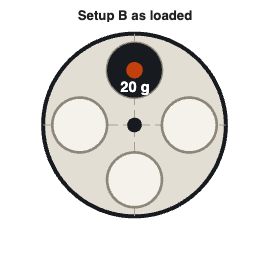

Starting in 3...
Starting in 2...
Starting in 1...


cfg.B = setupDisk("B", "Top", 1, loadMass_g, holderMass_g);

Recording 1 s at rest...
Motor ON: 80% PWM for 10 s, recording acceleration...
Done: 574 samples at about 47 samples/s. RMS acceleration while spinning: 4.431 m/s^2
Motor stopped


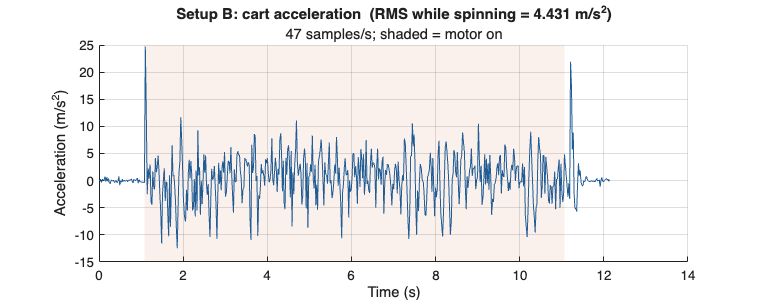

Saved /Users/atekes/Desktop/MECC Educational Session/Rotating Unbalance/version 4/Setup_B_accel.csv


if cfg.B.ready
    cfg.B.data = runMotor(a, pins, speed, runTime, accel, cfg.B);
    plotAccel(cfg.B.data);
    saveAccel(cfg.B.data);
end

## Setup C (two holders, opposite)

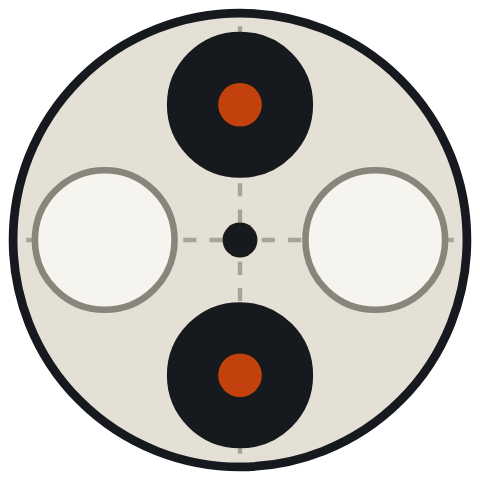

Run this section. A window opens: tick **which pockets** get a holder and set **how many 10 g loads** go in each one. Holders can carry different numbers of loads. The picture in the window shows where to put them. Load the disk, then click **Start motor**. Take your time; the motor waits for you.  Suggested: **two** holders in **opposite** pockets. The cart's acceleration is recorded, plotted and saved.

Setup C: set up the disk in the pop-up window...
Setup C: 2 holder(s). Top: 1 x 10 g = 10 g; Bottom: 1 x 10 g = 10 g. Total added: 20 g


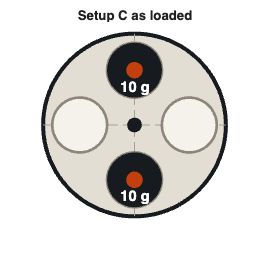

Starting in 3...
Starting in 2...
Starting in 1...


cfg.C = setupDisk("C", ["Top" "Bottom"], 1, loadMass_g, holderMass_g);

Recording 1 s at rest...
Motor ON: 80% PWM for 10 s, recording acceleration...
Done: 560 samples at about 46 samples/s. RMS acceleration while spinning: 3.220 m/s^2
Motor stopped


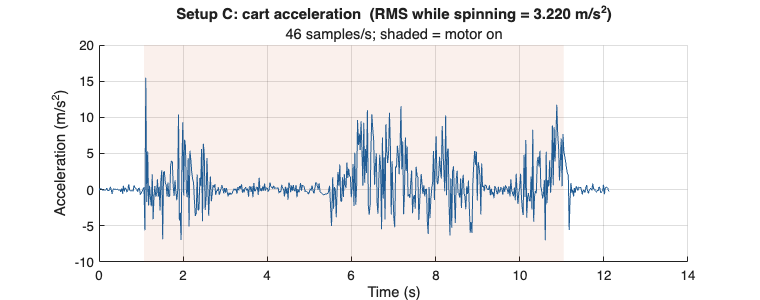

Saved /Users/atekes/Desktop/MECC Educational Session/Rotating Unbalance/version 4/Setup_C_accel.csv


if cfg.C.ready
    cfg.C.data = runMotor(a, pins, speed, runTime, accel, cfg.C);
    plotAccel(cfg.C.data);
    saveAccel(cfg.C.data);
end

## Setup D (three holders)

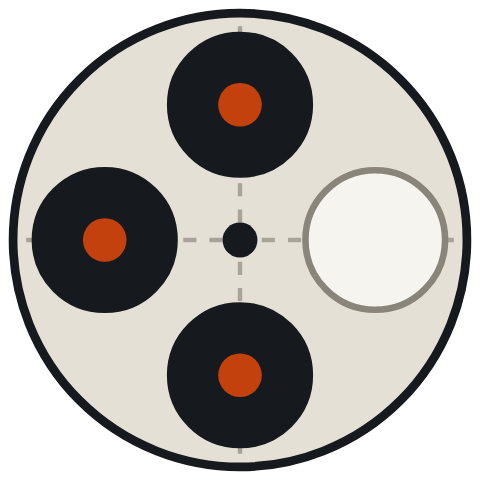

Run this section. A window opens: tick **which pockets** get a holder and set **how many 10 g loads** go in each one. Holders can carry different numbers of loads. The picture in the window shows where to put them. Load the disk, then click **Start motor**. Take your time; the motor waits for you.  Suggested: **three** holders (one pocket stays empty). The cart's acceleration is recorded, plotted and saved.

Setup D: set up the disk in the pop-up window...
Setup D: 3 holder(s). Top: 2 x 10 g = 20 g; Bottom: 2 x 10 g = 20 g; Left: 1 x 10 g = 10 g. Total added: 50 g


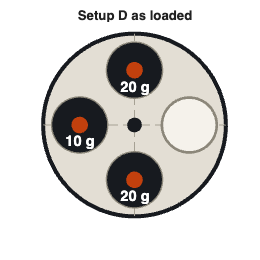

Starting in 3...
Starting in 2...
Starting in 1...


cfg.D = setupDisk("D", ["Top" "Left" "Bottom"], 1, loadMass_g, holderMass_g);

Recording 1 s at rest...
Motor ON: 80% PWM for 10 s, recording acceleration...
Done: 553 samples at about 45 samples/s. RMS acceleration while spinning: 2.579 m/s^2
Motor stopped


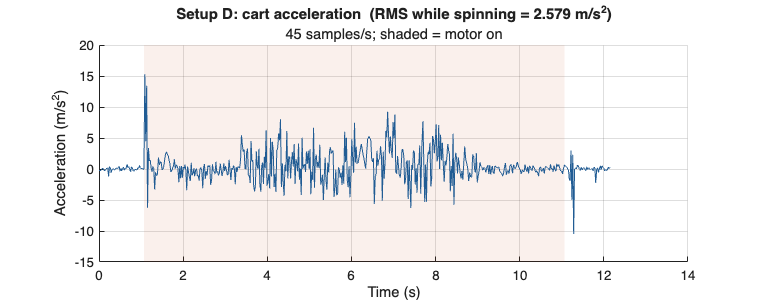

Saved /Users/atekes/Desktop/MECC Educational Session/Rotating Unbalance/version 4/Setup_D_accel.csv


if cfg.D.ready
    cfg.D.data = runMotor(a, pins, speed, runTime, accel, cfg.D);
    plotAccel(cfg.D.data);
    saveAccel(cfg.D.data);
end

## Record what you saw

Enter what you observed. The table compares it with your predictions and with the **measured RMS acceleration** of the cart (motor on). It also finds the main shaking frequency of each run (the disk speed) and, using your $\omega_n$, the frequency ratio $r$. The plot puts all four recordings on the same scale.

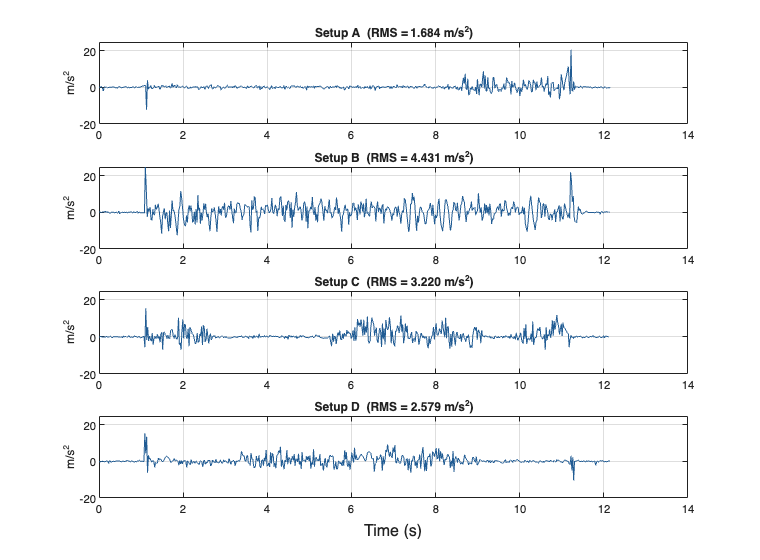

Observed = ["?"; "?"; "?"; "?"];       % "none", "small" or "large" for A, B, C, D   <-- EDIT
Match    = lower(strtrim(Prediction)) == lower(strtrim(Observed));
[RMS_accel, Freq_Hz] = compareRuns(cfg, ["A", "B", "C", "D"]);

if exist("wn", "var"), r_runs = 2*pi*Freq_Hz/wn; else, r_runs = nan(4, 1); end
results  = table(Setup, Prediction, Observed, Match, RMS_accel, Freq_Hz, r_runs, ...
                 'VariableNames', ["Setup", "Prediction", "Observed", "Match", ...
                                   "RMS accel (m/s^2)", "Shaking freq (Hz)", "r = w/wn"])

results = 4×7 table
          Setup           Prediction    Observed    Match    RMS accel (m/s^2)    Shaking freq (Hz)    r = w/wn
    __________________    __________    ________    _____    _________________    _________________    ________

    "A: no load"             "?"          "?"       true          1.6841                2.0004          0.34373
    "B: one holder"          "?"          "?"       true           4.431                 5.009           0.8607
    "C: two, opposite"       "?"          "?"       true          3.2196                1.0007          0.17195
    "D: three holders"       "?"          "?"       true          2.5789               0.55534         0.095424


## Bonus: find resonance

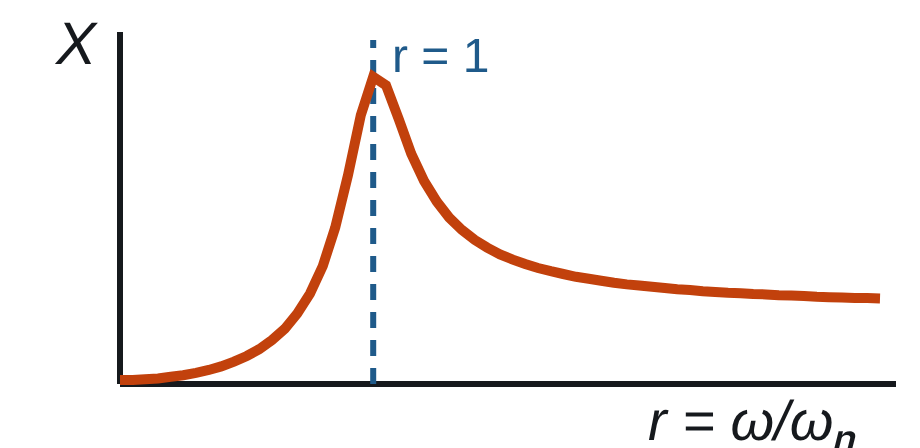

Go back to **setup B** (one holder). Run this section and set up the disk in the window (one holder). It then raises the motor speed slowly and prints each speed setting while recording acceleration. Watch for the setting where the cart shakes most, and what happens above it. The second plot shows the measured RMS acceleration at each speed setting. If you characterized the cart, a dashed line marks the estimated setting where $r$ = 1 (the disk turns at the natural frequency), and a table lists the estimated r for each setting.

Setup B (bonus): set up the disk in the pop-up window...
Setup B (bonus): 1 holder(s). Top: 1 x 10 g = 10 g. Total added: 10 g


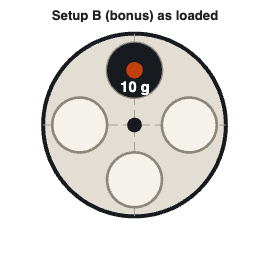

Starting in 3...
Starting in 2...
Starting in 1...


sweepSpeeds = 0.30:0.05:1.00;    % PWM settings to step through   <-- EDIT
holdTime    = 3;                 % seconds at each setting
cfg.Bonus = setupDisk("B (bonus)", "Top", 1, loadMass_g, holderMass_g);

Recording 1 s at rest...
Speed setting 0.30  (30% PWM)
Speed setting 0.35  (35% PWM)
Speed setting 0.40  (40% PWM)
Speed setting 0.45  (45% PWM)
Speed setting 0.50  (50% PWM)
Speed setting 0.55  (55% PWM)
Speed setting 0.60  (60% PWM)
Speed setting 0.65  (65% PWM)
Speed setting 0.70  (70% PWM)
Speed setting 0.75  (75% PWM)
Speed setting 0.80  (80% PWM)
Speed setting 0.85  (85% PWM)
Speed setting 0.90  (90% PWM)
Speed setting 0.95  (95% PWM)
Speed setting 1.00  (100% PWM)
Largest RMS acceleration at speed setting 0.65
Motor stopped


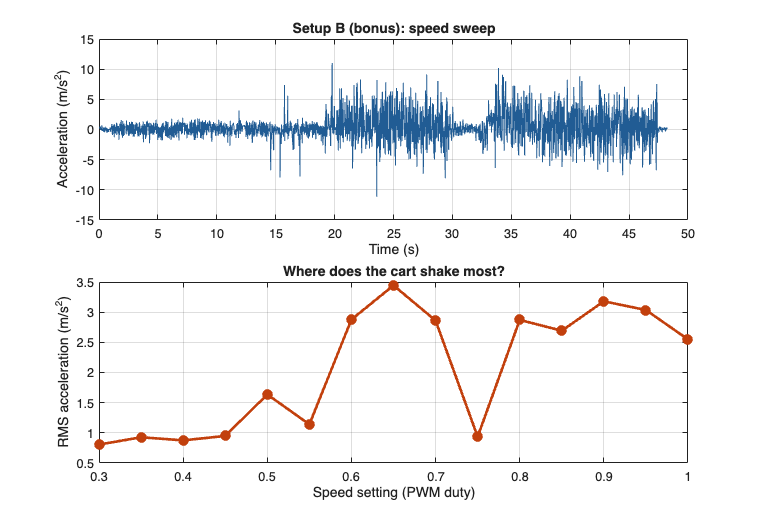

The shaking frequency could not be measured reliably at each step (about 46 samples/s), so r = 1 is not marked. Use the speed setting where the cart shook most.
    Speed_setting    RMS_accel    Freq_measured_Hz    r_estimated
    _____________    _________    ________________    ___________

         0.3          0.80471          9.9754             NaN    
        0.35          0.92692          10.948             NaN    
         0.4          0.87519          22.881             NaN    
        0.45          0.94812            13.7             NaN    
         0.5           1.6363          1.4284             NaN    
        0.55           1.1401          23.474             NaN    
         0.6           2.8773          13.361             NaN    
        0.65           3.4436           7.628             NaN    
         0.7           2.8616           11

Saved /Users/atekes/Desktop/MECC Educational Session/Rotating Unbalance/version 4/Setup_Bbonus_accel.csv


if cfg.Bonus.ready
    cfg.Bonus.data = sweepMotor(a, pins, sweepSpeeds, holdTime, accel, cfg.Bonus);
    if exist("wn", "var"), plotSweep(cfg.Bonus.data, wn); else, plotSweep(cfg.Bonus.data); end
    saveAccel(cfg.Bonus.data);
end

shakiestSetting = NaN;    % speed setting where the cart shook most   <-- EDIT
aboveThat = "?";          % what the cart did above that speed         <-- EDIT

## 5  Explain it

**Net unbalance.** Each holder is an arrow of size $m_0 e$ pointing from the shaft to the holder. Run this section to add the arrows for each setup, using the loads and pockets you entered (red = net arrow). Compare with the arrows you drew.

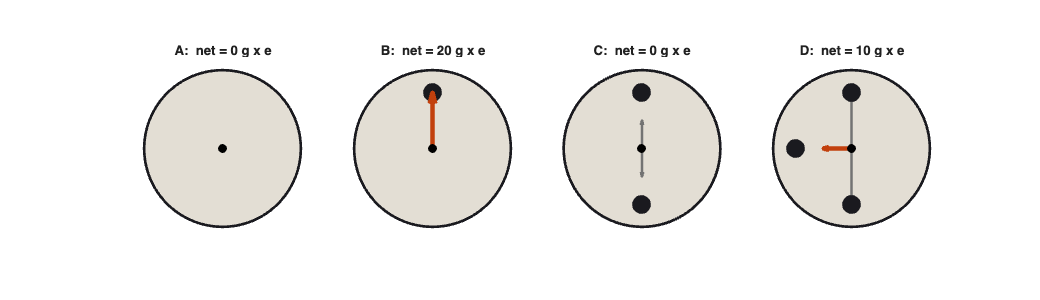

labels    = ["A", "B", "C", "D"];
defAngles = {[], 90, [90 270], [90 180 270]};     % used for any setup you skipped
angles = defAngles;
masses = cellfun(@(x) (holderMass_g + loadMass_g)*ones(size(x)), defAngles, 'UniformOutput', false);
for k = 1:4
    f = char(labels(k));
    if isfield(cfg, f) && cfg.(f).ready
        angles{k} = cfg.(f).angles;
        masses{k} = cfg.(f).mass_g;
    end
end
netUnbalance = plotUnbalanceArrows(angles, masses, labels);

Holders   = cellfun(@numel, angles)';
AddedMass = cellfun(@sum, masses)';
table(Setup, Holders, AddedMass, netUnbalance, ...
      'VariableNames', ["Setup", "Holders", "Added mass (g)", "Net unbalance (g x e)"])

ans = 4×4 table
          Setup           Holders    Added mass (g)    Net unbalance (g x e)
    __________________    _______    ______________    _____________________

    "A: no load"             0              0                    0          
    "B: one holder"          1             20                   20          
    "C: two, opposite"       2             20                    0          
    "D: three holders"       3             50                   10          


**Speed counts twice.** Run this section to plot the amplitude equation, starting with **your measured** $\zeta$. Change the list to see what damping does near $r=1$.

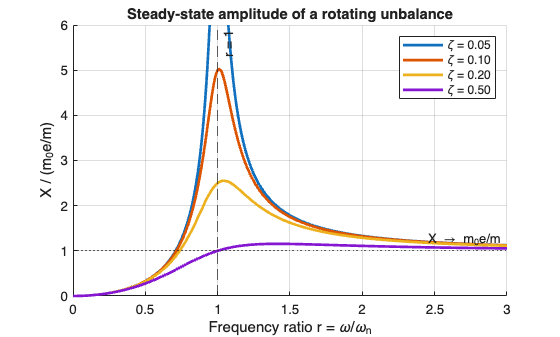

if exist("zeta", "var")
    zetaList = [zeta 0.1 0.2 0.5];    % your measured damping ratio first   <-- EDIT
else
    zetaList = [0.05 0.1 0.2 0.5];
end
r = linspace(0, 3, 600);
figure; hold on;
for z = zetaList
    plot(r, r.^2 ./ sqrt((1 - r.^2).^2 + (2*z*r).^2), 'LineWidth', 2, ...
         'DisplayName', sprintf('\\zeta = %.2f', z));
end
xline(1, '--', 'r = 1', 'HandleVisibility', 'off');
yline(1, ':', 'X \rightarrow m_0e/m', 'HandleVisibility', 'off');
xlabel('Frequency ratio r = \omega/\omega_n'); ylabel('X / (m_0e/m)');
title('Steady-state amplitude of a rotating unbalance'); legend; grid on; ylim([0 6]);

**1.** Setup C carries twice the added mass of B. Why does the cart shake less?

Your answer: ______________________________________________

**2.** Setup D has three holders. Which setup does it behave like, and why?

Your answer: ______________________________________________

**3.** From the amplitude equation, name two changes that cut vibration without removing holders.

Your answer: ______________________________________________

**4.** Name a real machine with this problem and how engineers fix it.

Your answer: ______________________________________________

## Takeaway

Vibration comes from the **net** unbalance $m_0 e$, not the total mass you add. Balancing means placing mass so the arrows cancel.

When you are done, run this section. It saves your system parameters, setups and acceleration data to **RotatingUnbalanceData.mat**, stops the motor and releases the Arduino.

vars = intersect(["cfg", "accel", "speed", "runTime", "free", "sysParams", "m_g", "m_kg", ...
                  "zeta", "wn", "fn", "k_eq", "k_each", "c"], string(who));
save("RotatingUnbalanceData.mat", vars{:});
disp("Saved RotatingUnbalanceData.mat")

Saved RotatingUnbalanceData.mat


stopMotor(a, pins);

Motor stopped


clear a

## Helper function files

This Live Script uses these function files, kept in the **helpers** folder next to this .mlx (the Setup section adds it to the MATLAB path): findArduinoPort.m, motorSetup.m, setupDisk.m, drawDisk.m, runMotor.m, sweepMotor.m, newRecording.m, recordFor.m, readAccelVoltage.m, demoSettings.m, finishRecording.m, dominantFreq.m, recordFreeResponse.m, findFreePeaks.m, plotFreeResponse.m, plotAccel.m, plotSweep.m, saveAccel.m, compareRuns.m, setMotor.m, stopMotor.m, plotUnbalanceArrows.m. Because they are separate files, you can also call them from the Command Window, for example  **plotAccel(cfg.B.data)**.